# Primary side control for DWC

## Primary buck-boost parameters - initial

clc
t_step=0.5e-6;
s_fre=20000;%switching frequency PWM
T=1/s_fre;
Lb=0.05; %reduced by /100 to improve response time
Cb=0.00015;
Rb = 1; %Lowering to 1e-1 and beyond, ruins system stability.
C_eq = 0.0015/100/1.9/1.3;
L_eq = 0.05*1.3;
R_eq = 100;
Vs=415;
Vl=400;
% Vc=Vl+5;
Vc = 1.2e3;

D=Vc/Vs/(1+Vc/Vs)

D = 0.7430

Io=(Vc-Vl)/(Rb + R_eq + 2*pi*s_fre*L_eq) %combine inductance at operating freq

Io = 0.0967


Il=Io/(1-D)

Il = 0.3765

k = 1/20;
kp_1 = 1

kp_1 = 1

kp=kp_1;
ki_1 = 100

ki_1 = 100

ki=ki_1;


## DWC params


%MOSFET
Rds=80e-3;
%PWM
m = 0.9; %modulation index


f_opt = 8.5483e+04;

C1 = 2.3101e-09;
C2 = 2.3101e-09;
L1 = 0.0015;
R1 = 0.8256;
L2 = 0.0015;
R2 = 0.8256;

M = 4.8583e-05;


R_load = 30.3;
Vb = 400;

## Kp Ki Values

zeta = 1/sqrt(2);
t_r = .1;
wn = 4.25/zeta/t_r

wn = 60.1041


% Cb = Cb+C_eq; % parallel capcitors

syms kp ki alpha
% coefficients correspond to A matrix
b=-(1-D)/Lb-(Vs+Vc)/Lb*kp;
c=(Vs+Vc)/Lb*ki;
d=(1-D)/Cb;
e=-1/(Cb*Rb)+Il/Cb*kp;
f=-Il/Cb*ki;
h=-1;


eq1 = -e == 2*zeta*wn+alpha;
eq2 = f-b*d == wn^2+2*zeta*wn*alpha;
eq3 = -c*d*h == alpha*wn^2;

[kp,ki,alpha] = solve([eq1,eq2,eq3],[kp,ki,alpha]);
alpha=double(alpha)

alpha = 2.6557e+05

kp=double(kp)

kp = 0.0101

ki=double(ki)

ki = 0.4335

k = 1;



%----------Verify----------------
% k=1/Vs; set k to 1 when using above solution
k=1;
kp_1=double(kp);
ki_1=double(ki);
kp=k*kp_1;
ki=k*ki_1;
A=zeros(3);
A(1,2)=-(1-D)/Lb-(Vs+Vc)/Lb*kp;
A(1,3)=(Vs+Vc)/Lb*ki;
A(2,1)=(1-D)/Cb;
A(2,2)=-1/(Cb*Rb)+Il/Cb*kp;
A(2,3)=-Il/Cb*ki;
A(3,2)=-1;
B(1,1)=(Vs+Vc)/Lb*kp;
B(2,1)=-Il/Cb*kp;
B(3,1)=1;

D_eig1=eig(A)

D_eig1 = 	1.0e+05 *

  -2.6557 + 0.0000i
  -0.0004 + 0.0004i
  -0.0004 - 0.0004i


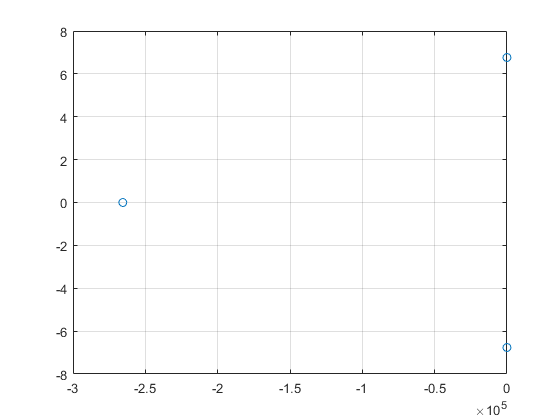

D_eig1_real=real(D_eig1);
D_eig1_ima=imag(D_eig1);

figure
scatter(D_eig1_real,D_eig1_ima/2/pi)
grid on
box on

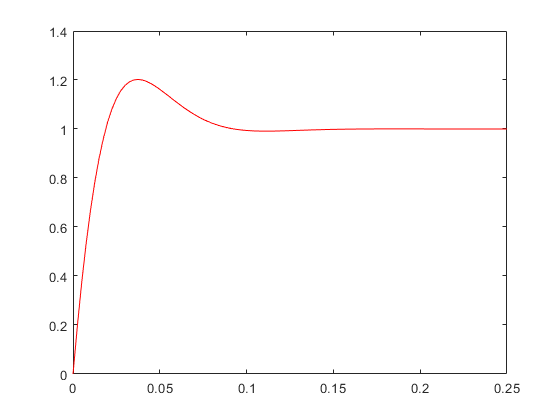


s = tf('s');
b = A(1,2);
c = A(1,3);
d = A(2,1);
e = A(2,2);
f = A(2,3);
h = A(3,2);
tf_test = 1/(s^3+s^2*-e+s*(f-b*d)+c*d*-h);
% figure;pzmap(tf_test);grid on;

AA=eye(3)*s-A;
tf1=inv(AA)*B;
figure
% plot(Il_sim.Time-0.2,Il_sim.Data,'-b')
% xlim([0 0.2])
% ylim([0 3])
% hold on
% plot(vc_sim.Time-3,vc_sim.Data,'-b')
% xlim([0 3])
% hold on
[y,tout]=step(tf1(2),0.25);
plot(tout,y,'-r')

% grid on
% hold on

## Compare to sim output

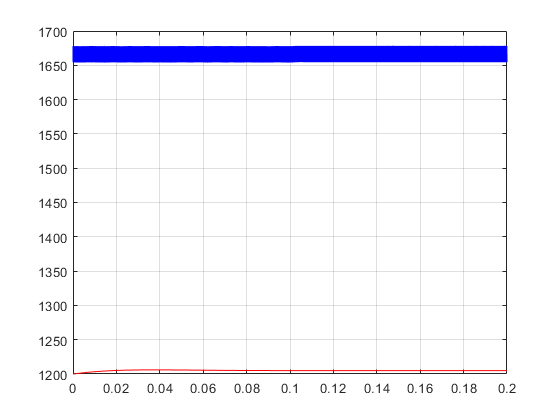

figure
plot(vc_sim.Time-0.4,vc_sim.Data,'-b')
xlim([0 0.2])
hold on
[y,tout]=step(tf1(2),0.2);
plot(tout,y*5+Vc,'-r')
grid on
hold on